# **Diferenciación**

Este ejemplo muestra cómo **encontrar **y** evaluar** derivadas de manera analítica utilizando Symbolic Math Toolbox™. En el ejemplo, encontrarás la 1ª y 2ª derivada de $f\left(x\right)$ y usarás estas derivadas para encontrar máximos locales, mínimos locales y puntos de inflexión.

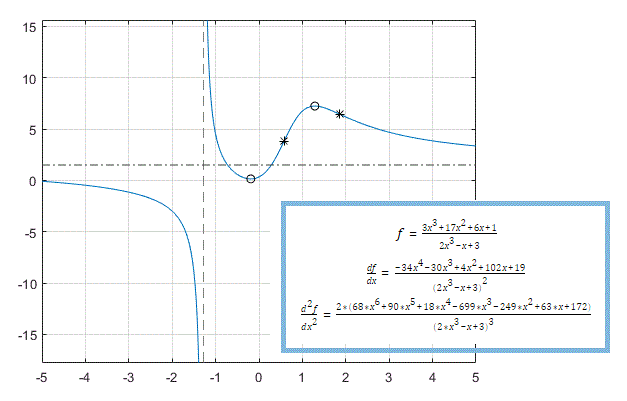

## Primera derivada: encontrando mínimos y máximos locales

Calcular la primera derivada de una expresión te ayuda a encontrar los mínimos y máximos locales de esa expresión. Antes de crear una expresión simbólica, declara las variables simbólicas:

syms x

Por defecto, las soluciones que incluyen componentes imaginarios se incluyen en los resultados. Aquí, considera solo los valores reales de $x$ estableciendo la suposición de que $x$ es real:

assume(x, 'real')

Como ejemplo, crea una expresión racional (ejemplo, una fracción donde el numerador y el denominador son expresiones polinomiales) 

f = (3*x^3 + 17*x^2 + 6*x + 1)/(2*x^3 - x + 3)

$$f = \frac{3\,x^{3}+17\,x^{2}+6\,x+1}{2\,x^{3}-x+3}$$

Gráficando esta expresión muestra que la expresión tiene asintotas horizales y verticales, un mínimo local entre -1 y 0, y un máximo local entre 1 y 2.

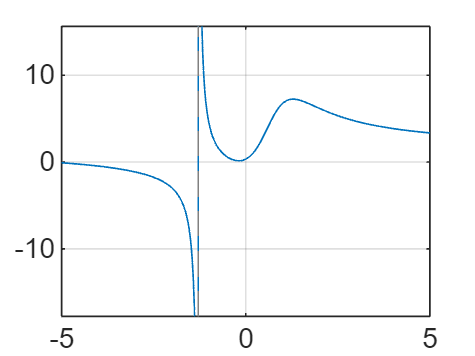

fplot(f)
grid

Para encontrar la asintota horizontal, calcule el limite de $f$para $x$ cuando tiende a infinito positivo y negativo. 

***La asintota horizontal es ***`y = 3/2.`

lim_left = limit(f, x, -inf)

$$lim\_left = \frac{3}{2}$$

lim_right = limit(f, x, inf)

$$lim\_right = \frac{3}{2}$$

Agregando la asintota horizontal al gráfico.

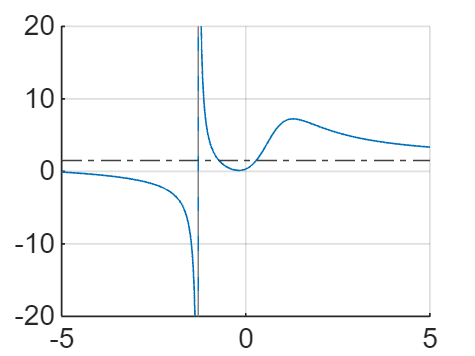

hold on
plot(xlim, [lim_right lim_right], 'LineStyle', '-.', 'Color', [0.25 0.25 0.25])

Ahora, para encontrar la asíntota vertical de $f,$ encuentra los polos de $f\ldotp$

pole_pos = poles(f, x)

$$pole\_pos = -\frac{1}{6\,{\left(\frac{3}{4}-\frac{\sqrt{241}\,\sqrt{432}}{432}\right)}^{1/3}}-{\left(\frac{3}{4}-\frac{\sqrt{241}\,\sqrt{432}}{432}\right)}^{1/3}$$

Aproxime la solución exacta númerica usando la función `double.`

double(pole_pos)

ans = -1.2896

Ahora, vamos a encontrar el máximo y mínimo local de $f\ldotp$Si un punto corresponde a los puntos extremos(máximos o mínimos), la primera derivada de la expresión en ese punto es  igual a cero. Puede calcular la derivada de $f$usando `diff.`

g = diff(f, x)

$$g = \frac{9\,x^{2}+34\,x+6}{2\,x^{3}-x+3}-\frac{\left(6\,x^{2}-1\right)\,\left(3\,x^{3}+17\,x^{2}+6\,x+1\right)}{{\left(2\,x^{3}-x+3\right)}^{2}}$$

To find the local extrema of `f`, solve the equation 

Para encontrar los extremos locales de $f,$ resuelva la ecuación `g == 0`:

g0 = solve(g, x)

$$g0 = \begin{array}{l} \left(\begin{array}{c} \frac{\sqrt{\sigma_{2}}}{6\,{\sigma_{3}}^{1/6}}-\sigma_{1}-\frac{15}{68}\\ \frac{\sqrt{\sigma_{2}}}{6\,{\sigma_{3}}^{1/6}}+\sigma_{1}-\frac{15}{68} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{\frac{337491\,\sqrt{6}\,\sqrt{\frac{3\,\sqrt{3}\,\sqrt{178939632355}}{9826}+\frac{2198209}{9826}}}{39304}+\frac{2841\,{\sigma_{3}}^{1/3}\,\sqrt{\sigma_{2}}}{578}-9\,{\sigma_{3}}^{2/3}\,\sqrt{\sigma_{2}}-\frac{361\,\sqrt{\sigma_{2}}}{289}}}{6\,{\sigma_{3}}^{1/6}\,{\sigma_{2}}^{1/4}}\\ \sigma_{2}=\frac{2841\,{\sigma_{3}}^{1/3}}{1156}+9\,{\sigma_{3}}^{2/3}+\frac{361}{289}\\ \sigma_{3}=\frac{\sqrt{3}\,\sqrt{178939632355}}{176868}+\frac{2198209}{530604} \end{array}$$

Aproxime la solución exacta númericamente usando la función `double.`

double(g0)

ans =    -0.1892
    1.2860


La expresión $f$tiene un máximo local en $x\;=1\ldotp 286$y un mínimo local en $x=-0\ldotp 189$. Obtenemos estos valores de la función en estos puntos usando `subs`:

f0 = subs(f,x,g0)

$$f0 = \begin{array}{l} \left(\begin{array}{c} \frac{3\,\sigma_{2}-17\,{\left(\sigma_{5}-\sigma_{6}+\frac{15}{68}\right)}^{2}-\sigma_{4}+\sigma_{1}+\frac{11}{34}}{\sigma_{6}+2\,\sigma_{2}-\sigma_{5}-\frac{219}{68}}\\ -\frac{\sigma_{4}+17\,{\left(\sigma_{6}+\sigma_{5}-\frac{15}{68}\right)}^{2}+3\,\sigma_{3}+\sigma_{1}-\frac{11}{34}}{\sigma_{6}-2\,\sigma_{3}+\sigma_{5}-\frac{219}{68}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sigma_{7}}{{\sigma_{9}}^{1/6}\,{\sigma_{8}}^{1/4}}\\ \sigma_{2}={\left(\sigma_{5}-\sigma_{6}+\frac{15}{68}\right)}^{3}\\ \sigma_{3}={\left(\sigma_{6}+\sigma_{5}-\frac{15}{68}\right)}^{3}\\ \sigma_{4}=\frac{\sqrt{\sigma_{8}}}{{\sigma_{9}}^{1/6}}\\ \sigma_{5}=\frac{\sigma_{7}}{6\,{\sigma_{9}}^{1/6}\,{\sigma_{8}}^{1/4}}\\ \sigma_{6}=\frac{\sqrt{\sigma_{8}}}{6\,{\sigma_{9}}^{1/6}}\\ \sigma_{7}=\sqrt{\frac{337491\,\sqrt{6}\,\sqrt{\frac{3\,\sqrt{3}\,\sqrt{178939632355}}{9826}+\frac{2198209}{9826}}}{39304}+\frac{2841\,{\sigma_{9}}^{1/3}\,\sqrt{\sigma_{8}}}{578}-9\,{\sigma_{9}}^{2/3}\,\sqrt{\sigma_{8}}-\frac{361\,\sqrt{\sigma_{8}}}{289}}\\ \sigma_{8}=\frac{2841\,{\sigma_{9}}^{1/3}}{1156}+9\,{\sigma_{9}}^{2/3}+\frac{361}{289}\\ \sigma_{9}=\frac{\sqrt{3}\,\sqrt{178939632355}}{176868}+\frac{2198209}{530604} \end{array}$$

Aproxime la solución exacta númericamente usando la función `double `en la variable `f0`

double(f0)

ans =     0.1427
    7.2410


Agrega marcadores de puntos al gráfico en los extremos.

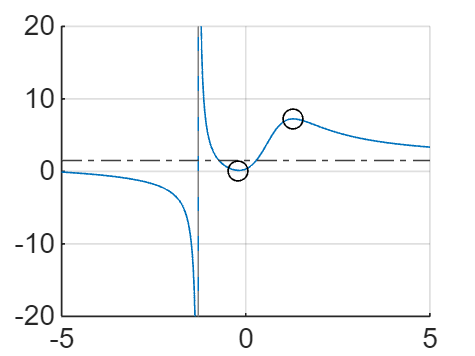

plot(g0, f0, 'ok')

## Segunda derivada: Encontrar puntos de inflexión

Calcular la segunda derivada te permite encontrar los puntos de inflexión de la expresión. La manera más eficiente de calcular derivadas de segundo orden o de orden superior es usar el parámetro que especifica el orden de la derivada

h = diff(f, x, 2)

$$h = \begin{array}{l} \frac{18\,x+34}{\sigma_{1}}-\frac{2\,\left(6\,x^{2}-1\right)\,\left(9\,x^{2}+34\,x+6\right)}{{\sigma_{1}}^{2}}-\frac{12\,x\,\sigma_{2}}{{\sigma_{1}}^{2}}+\frac{2\,{\left(6\,x^{2}-1\right)}^{2}\,\sigma_{2}}{{\sigma_{1}}^{3}}\\ \mathrm{where}\\ \sigma_{1}=2\,x^{3}-x+3\\ \sigma_{2}=3\,x^{3}+17\,x^{2}+6\,x+1 \end{array}$$

Simplificando el resultado

h = simplify(h)

$$h = \frac{2\,\left(68\,x^{6}+90\,x^{5}+18\,x^{4}-699\,x^{3}-249\,x^{2}+63\,x+172\right)}{{\left(2\,x^{3}-x+3\right)}^{3}}$$

Para encontrar los puntos de inflexión de $f$, resuelve la ecuación $h=0$. Aquí, usa el solucionador numérico `vpasolve` para calcular aproximaciones en punto flotante de las soluciones:

h0 = vpasolve(h, x)

$$h0 = \left(\begin{array}{c} 0.57871842655441748319601085860196\\ 1.8651543689917122385037075917613\\ -1.4228127856020972275345064554049-1.8180342567480118987898749770461\,\mathrm{i}\\ -1.4228127856020972275345064554049+1.8180342567480118987898749770461\,\mathrm{i}\\ -0.46088831805332057449182335801198+0.47672261854520359440077796751805\,\mathrm{i}\\ -0.46088831805332057449182335801198-0.47672261854520359440077796751805\,\mathrm{i} \end{array}\right)$$

La expresión $f$ tiene dos puntos de inflexión, $x=1\ldotp 865$ y $x=0\ldotp 579$. Identifique que `vpasolve`  retorna igualmente las soluciones complejas, por lo que se pueden descartar.

h0(imag(h0)~=0) = []

$$h0 = \left(\begin{array}{c} 0.57871842655441748319601085860196\\ 1.8651543689917122385037075917613 \end{array}\right)$$

Add markers to the plot showing the inflection points:

Agregue marcadores de puntos al grafico para mostrar 

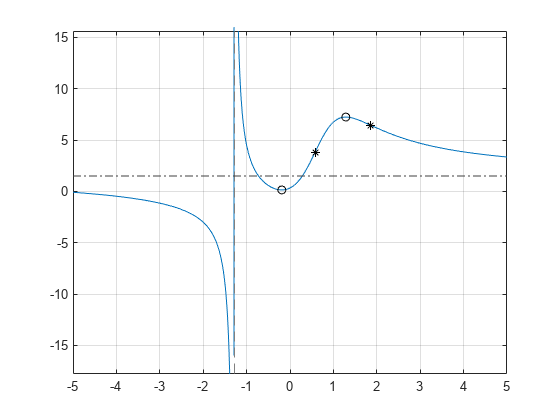

plot(h0, subs(f,x,h0), '*k')
hold off

*Copyright 2010-2016 The MathWorks, Inc.*